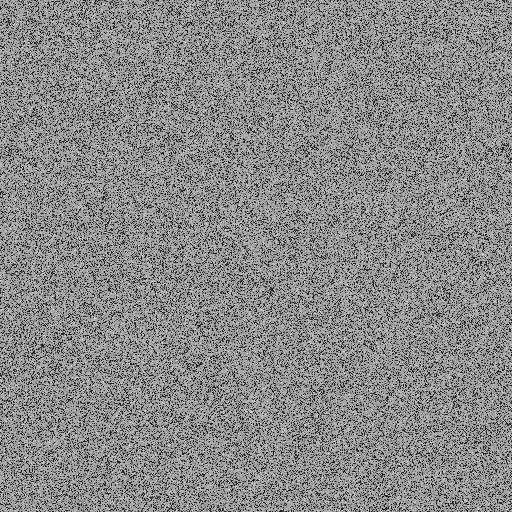

A=C;
[H,N]=size(A);
A1=reshape(A(Index),H,N);
A1=reshape(A1(Index),H,N);
A2=Diffusion(A1,chaoticList,rules,"diffuse");
% A2(1:H/2,1:N/2)=128;
figure
imshow(uint8(A1))

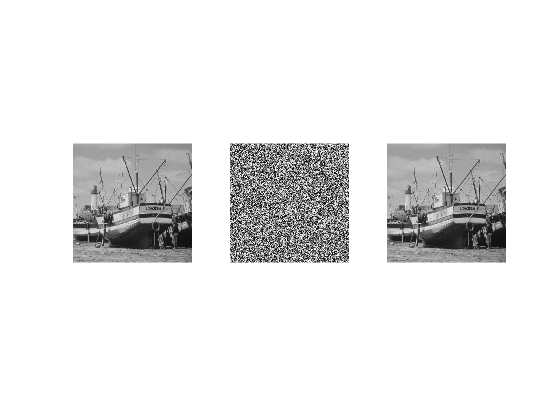

A3=Diffusion(A2,chaoticList,rules,"reverse");
[~,IIndex]=sort(Index);
A4=reshape(A3(IIndex),H,N);
figure
subplot(131)
imshow(uint8(A4))
subplot(132)
imshow(uint8(A2))
subplot(133)
imshow(uint8(A))

psnr(uint8(A4),uint8(A))

ans = Inf

ssim(uint8(A4),uint8(A))

ans = 1

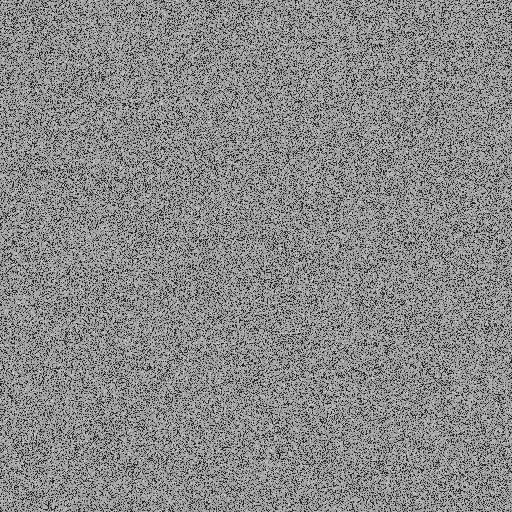

addpath('E:\BaiduSyncdisk\Matlab\2DCS-ETC-master\TDCS-ETC\mywork');                      %    functions

Index = randperm (H * N);                                       %    generate a random index for GRP operation

B1 = Scramble (Index, A);

B1 = Scramble (Index, A);

RBI_matrix = zeros (H, N);  %  generate a random binary integer matrix for  NPT operation
 
for i = 1: size_images
    
    for j = 1: size_images
        
        Permutation = randperm ( 2 )  ; 
        
        if Permutation (1) ==1
            
          RBI_matrix  (i, j) = 0;
           
        else
            
          RBI_matrix  (i, j) = 1;
          
        end
        
    end
    
end

% NPT encryption

B2 = negative_postive_transform (B1, RBI_matrix, H);

%B2(1:H/2,1:N/2)=128;
figure
imshow(uint8(B1))

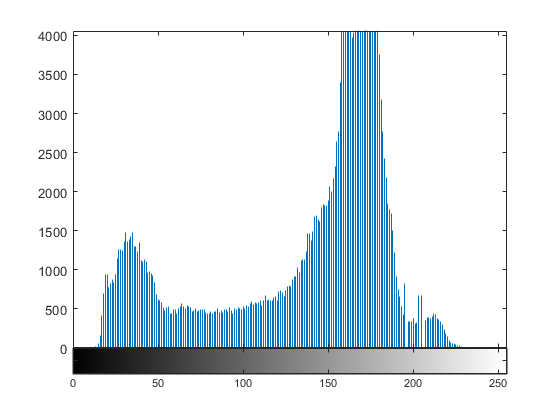

figure

imhist(uint8(A))

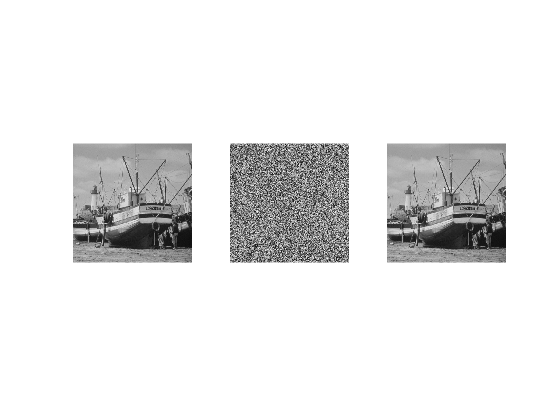


B3 = negative_postive_inverse_transform (B2, RBI_matrix, H);

B4 = Unscramble (Index, B3);
figure
subplot(131)
imshow(uint8(B4))
subplot(132)
imshow(uint8(B2))
subplot(133)
imshow(uint8(A))

psnr(uint8(B4),uint8(A))

ans = Inf

ssim(uint8(B4),uint8(A))

ans = 1